## Initialize

close
clearvars -except mapCD
addpath ..\od\OneDrive\matlab\myFunction\myftn\
fn = '..\od\OneDrive\matlab\RawData\1T-TaS2(point defect)\mapCD.mat';
loadif(fn);

fldNm = 1×1 cell array
    {'mapCD'}



Your variables are:

fldNm  fn     mt     



ans = 'already'

load ..\od\OneDrive\matlab\RawData\'1T-TaS2(point defect)'\grd.mat grd

## Tuning Parameter Setting

indLatts(:,:,1) = [1 39 21; 1 36 49];
shif_xys(:,:,1) = [-1 0 1;0 0 0];
indLatts(:,:,2) = [2 54 53; 1 30 66];
shif_xys(:,:,2) = [0 -2 0;0 1 0];

## DataProcessing

for iph = 1:2
    line_info =grd.line_info(iph,:,:);
    I_P__C = constructBases(line_info);
    szZ = size(mapCD.dt(iph).Z);
    a = consturctGrid(I_P__C,line_info,szZ);% less tuned coordinate
    b = a.latticeFineTune(indLatts(:,:,iph),shif_xys(:,:,iph));% more tuned coordinate
    as(iph) = a;
    bs(iph) = b;
end
abs = [as;bs];

## Visualization

validation check of the parameter

### Front Handles

iph = 2

iph = 2

### Drawing

figureSetting

gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0 .8 .8]);
f1.Visible = "on";

Background Image

Z = mapCD.dt(iph).Z;
BW = imregionalmax(Z,8);
Z = Z.*~BW;
views(Z);
tn = ['iph=' char(num2str(iph))];
title(tn)
colormap gray;
pZ = findobj('Type','image');
pZ.HitTest ="off"

pZ =   Image with properties:

           CData: [621×731 double]
    CDataMapping: 'scaled'

  Show all properties


3 points

hold on
p3s(:,:,1) = as(iph).oB2pC(indLatts(:,:,iph));
p3s(:,:,2) = p3s(:,:,1) + shif_xys(:,:,iph);
clrs = [1 0 0;0 1 0];
for iba = 1:2
    pp3s(iba) = plot(p3s(1,:,iba),p3s(2,:,iba),"o-");
    pp3s(iba).Color = clrs(iba,:);
end
hold off

Lattice

hold on
clrs = [1 0 0;0 1 0]

clrs =      1     0     0
     0     1     0


abs

abs = 2×2 grid2d array with properties:
    offset_stdpts
    a1_stdpts
    a2_stdpts
    sz_stdpts
    clr_a1
    clr_a2
    clr_faceWindow
    clr_edgeWindow
    augMat
    baryBss
    inLatt
    inGrid


for iba = 1:2
    pLs(iba) = abs(iba,iph).pLatticeWin;
    pLs(iba).Color = clrs(iba,:);
    pLs(iba).Marker ="."
end

ans = 'reCalculated'

xy =      9    11
     9    26
     9    41
     9    56
     9    71
     9    86
     9   101
     9   116
     9   131
     9   146
     9   161
     9   176
     9   191
     9   206
     9   221


ans = 'reCalculated'

ans = 'reCalculated'

pLs =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 1.5000
             Marker: '.'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 9 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 22.0182 … ] (1×2324 double)
              YData: [11 26 41 56 71 86 101 116 131 146 161 176 191 206 221 236 251 266 281 296 311 326 341 356 371 386 401 416 431 446 461 476 491 506 521 536 551 566 581 596 611 3.5000 18.5000 33.5000 48.5000 63.5000 78.5000 93.5000 … ] (1×2324 double)

  Show all pro

ans = 'reCalculated'

xy =     9.0831   10.9584
    9.1368   25.9316
    9.1904   40.9048
    9.2441   55.8780
    9.2977   70.8511
    9.3514   85.8243
    9.4050  100.7975
    9.4587  115.7706
    9.5124  130.7438
    9.5660  145.7170
    9.6197  160.6902
    9.6733  175.6633
    9.7270  190.6365
    9.7806  205.6097
    9.8343  220.5829


ans = 'reCalculated'

ans = 'reCalculated'

pLs =   1×2 Line array:

    Line    Line


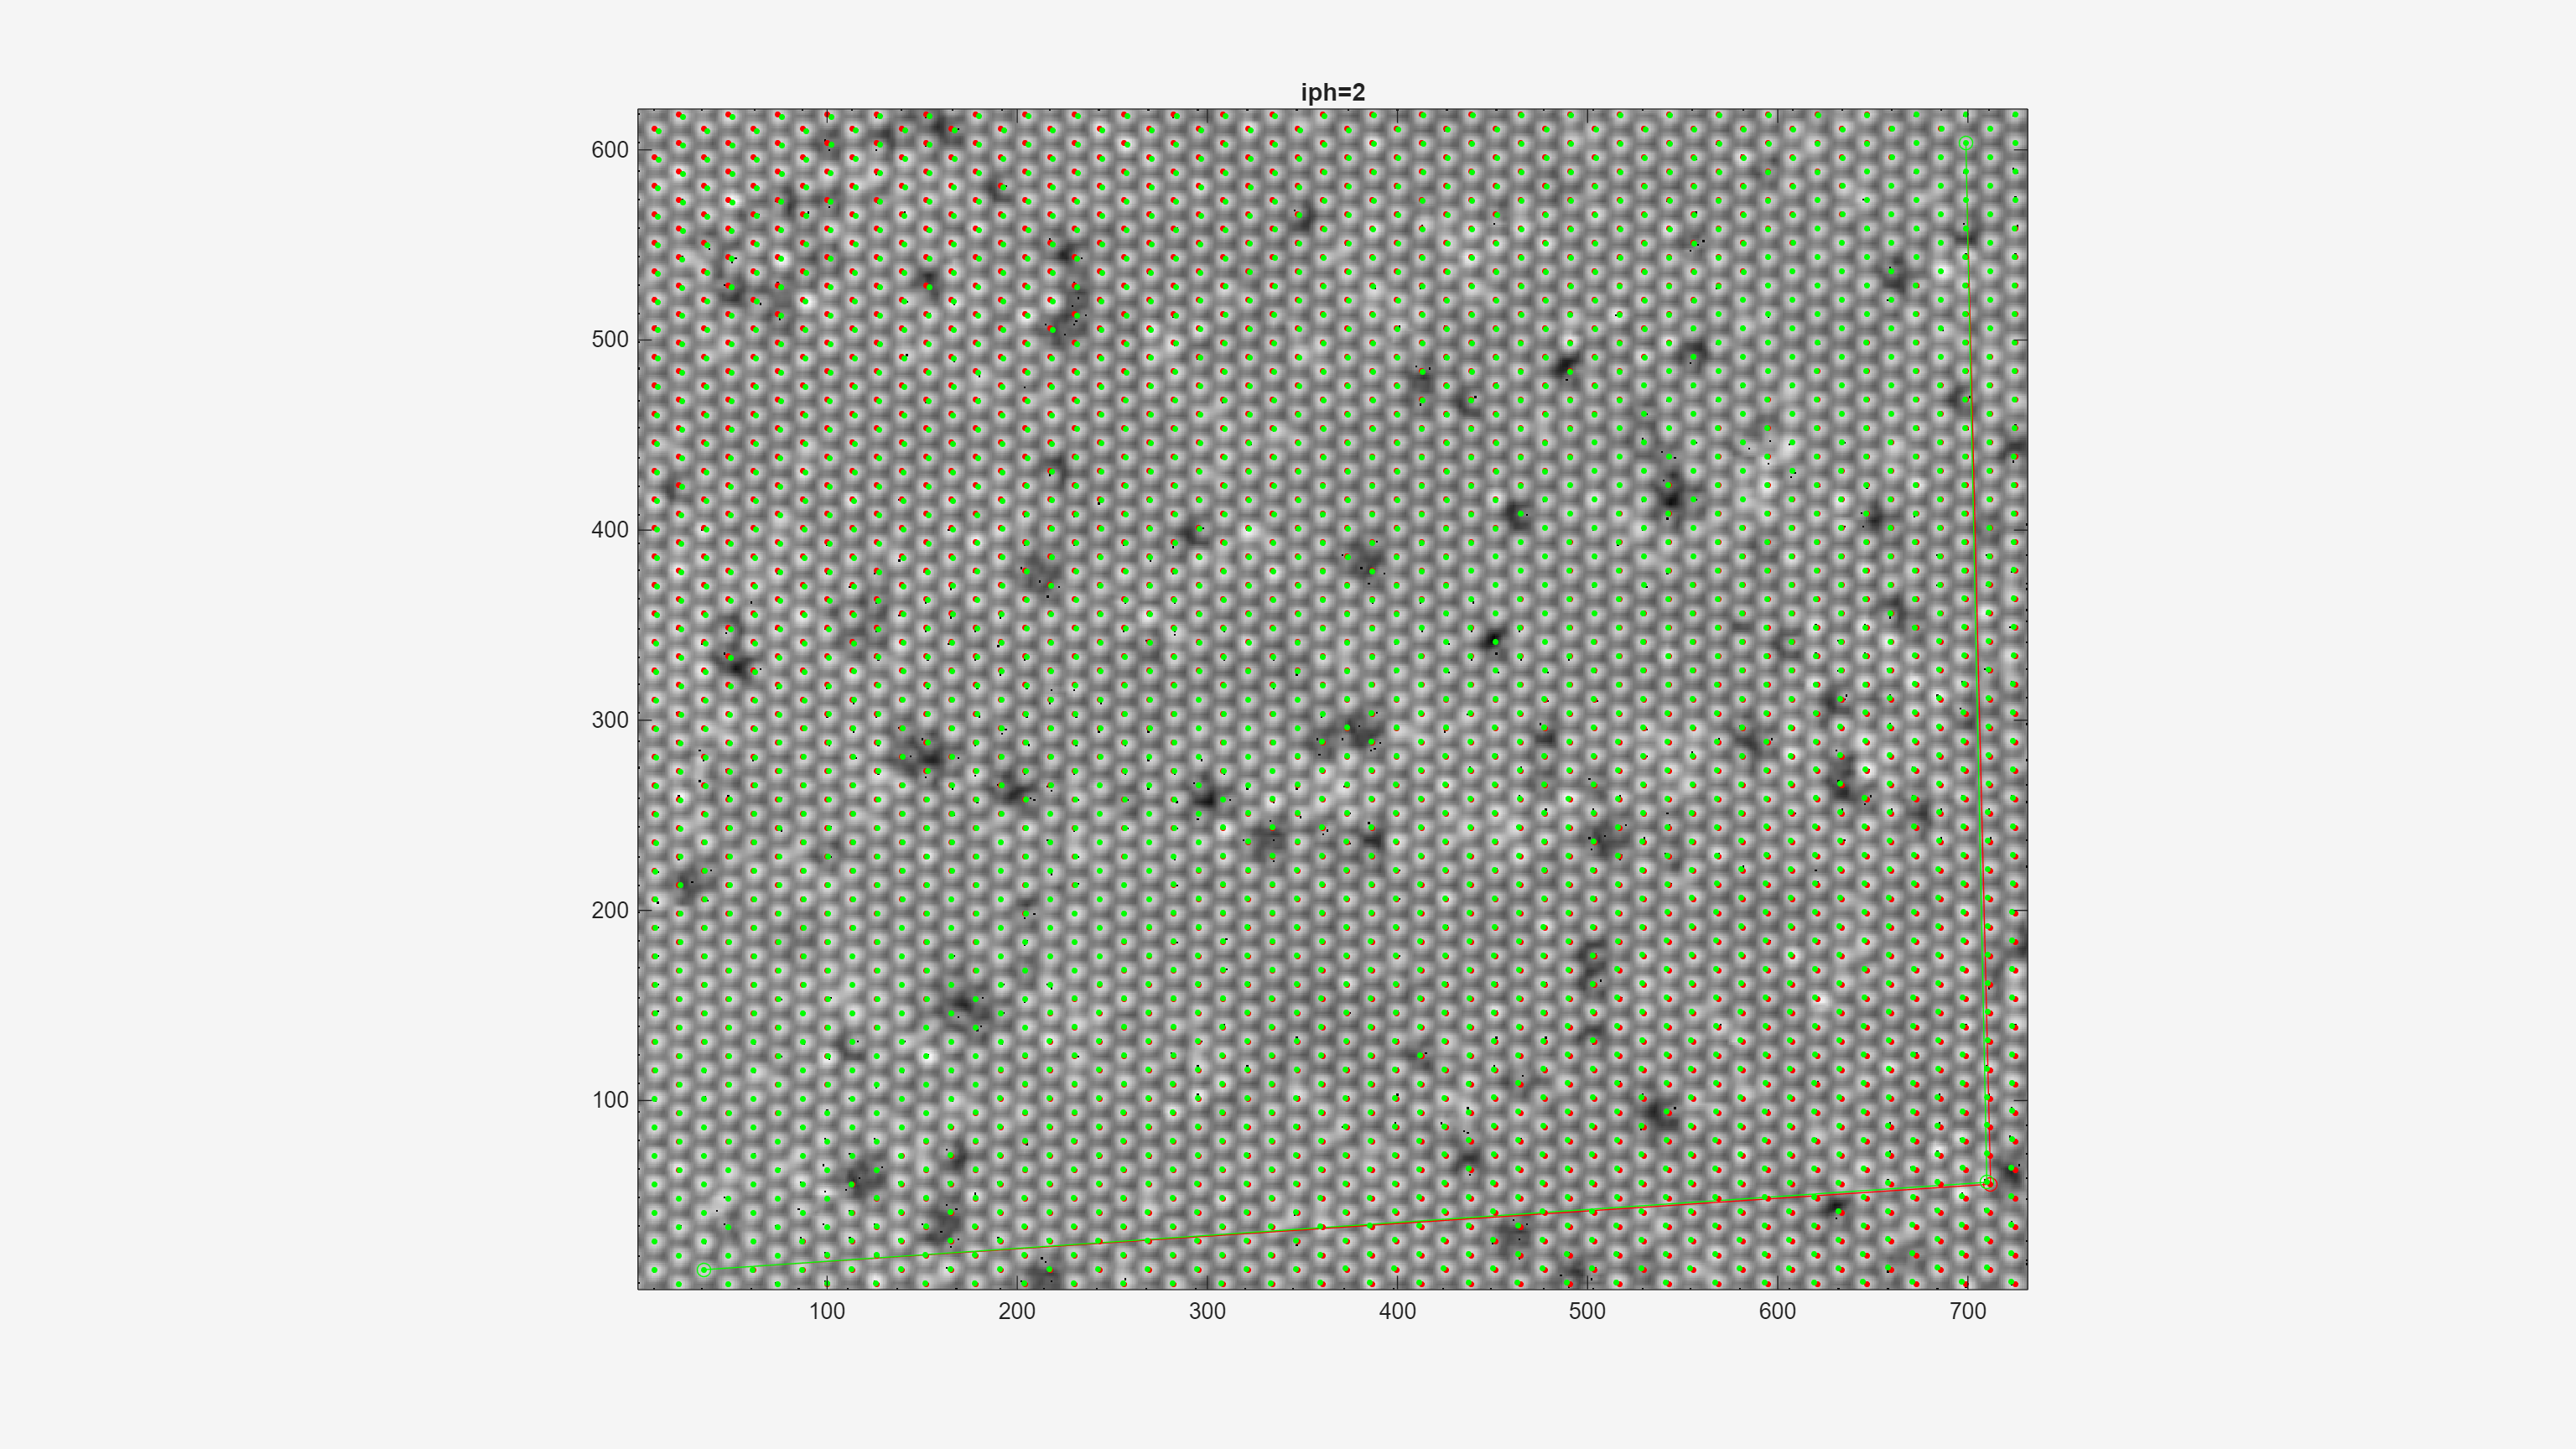

hold off

### Back Handles

Visibility

pZ.Visible = true

pZ =   Image with properties:

           CData: [621×731 double]
    CDataMapping: 'scaled'

  Show all properties


pLs(1).Visible = false

pLs =   1×2 Line array:

    Line    Line


pLs(2).Visible = false

pLs =   1×2 Line array:

    Line    Line


pp3s(1).Visible = true

pp3s =   1×2 Line array:

    Line    Line


pp3s(2).Visible = true

pp3s =   1×2 Line array:

    Line    Line


Lattice

pLs(1).Marker = "o"

pLs =   1×2 Line array:

    Line    Line


pLs(1).MarkerSize  = 10

pLs =   1×2 Line array:

    Line    Line


pLs(1).LineWidth = 1

pLs =   1×2 Line array:

    Line    Line


pLs(2).Marker = "o"

pLs =   1×2 Line array:

    Line    Line


pLs(2).MarkerSize  = 10

pLs =   1×2 Line array:

    Line    Line


pLs(2).LineWidth = 1

pLs =   1×2 Line array:

    Line    Line


3 points

pp3s(1).Marker = "o"

pp3s =   1×2 Line array:

    Line    Line


pp3s(1).MarkerSize  = 100

pp3s =   1×2 Line array:

    Line    Line


pp3s(1).LineWidth = 5

pp3s =   1×2 Line array:

    Line    Line


pp3s(2).Marker = "o"

pp3s =   1×2 Line array:

    Line    Line


pp3s(2).MarkerSize  = 100

pp3s =   1×2 Line array:

    Line    Line


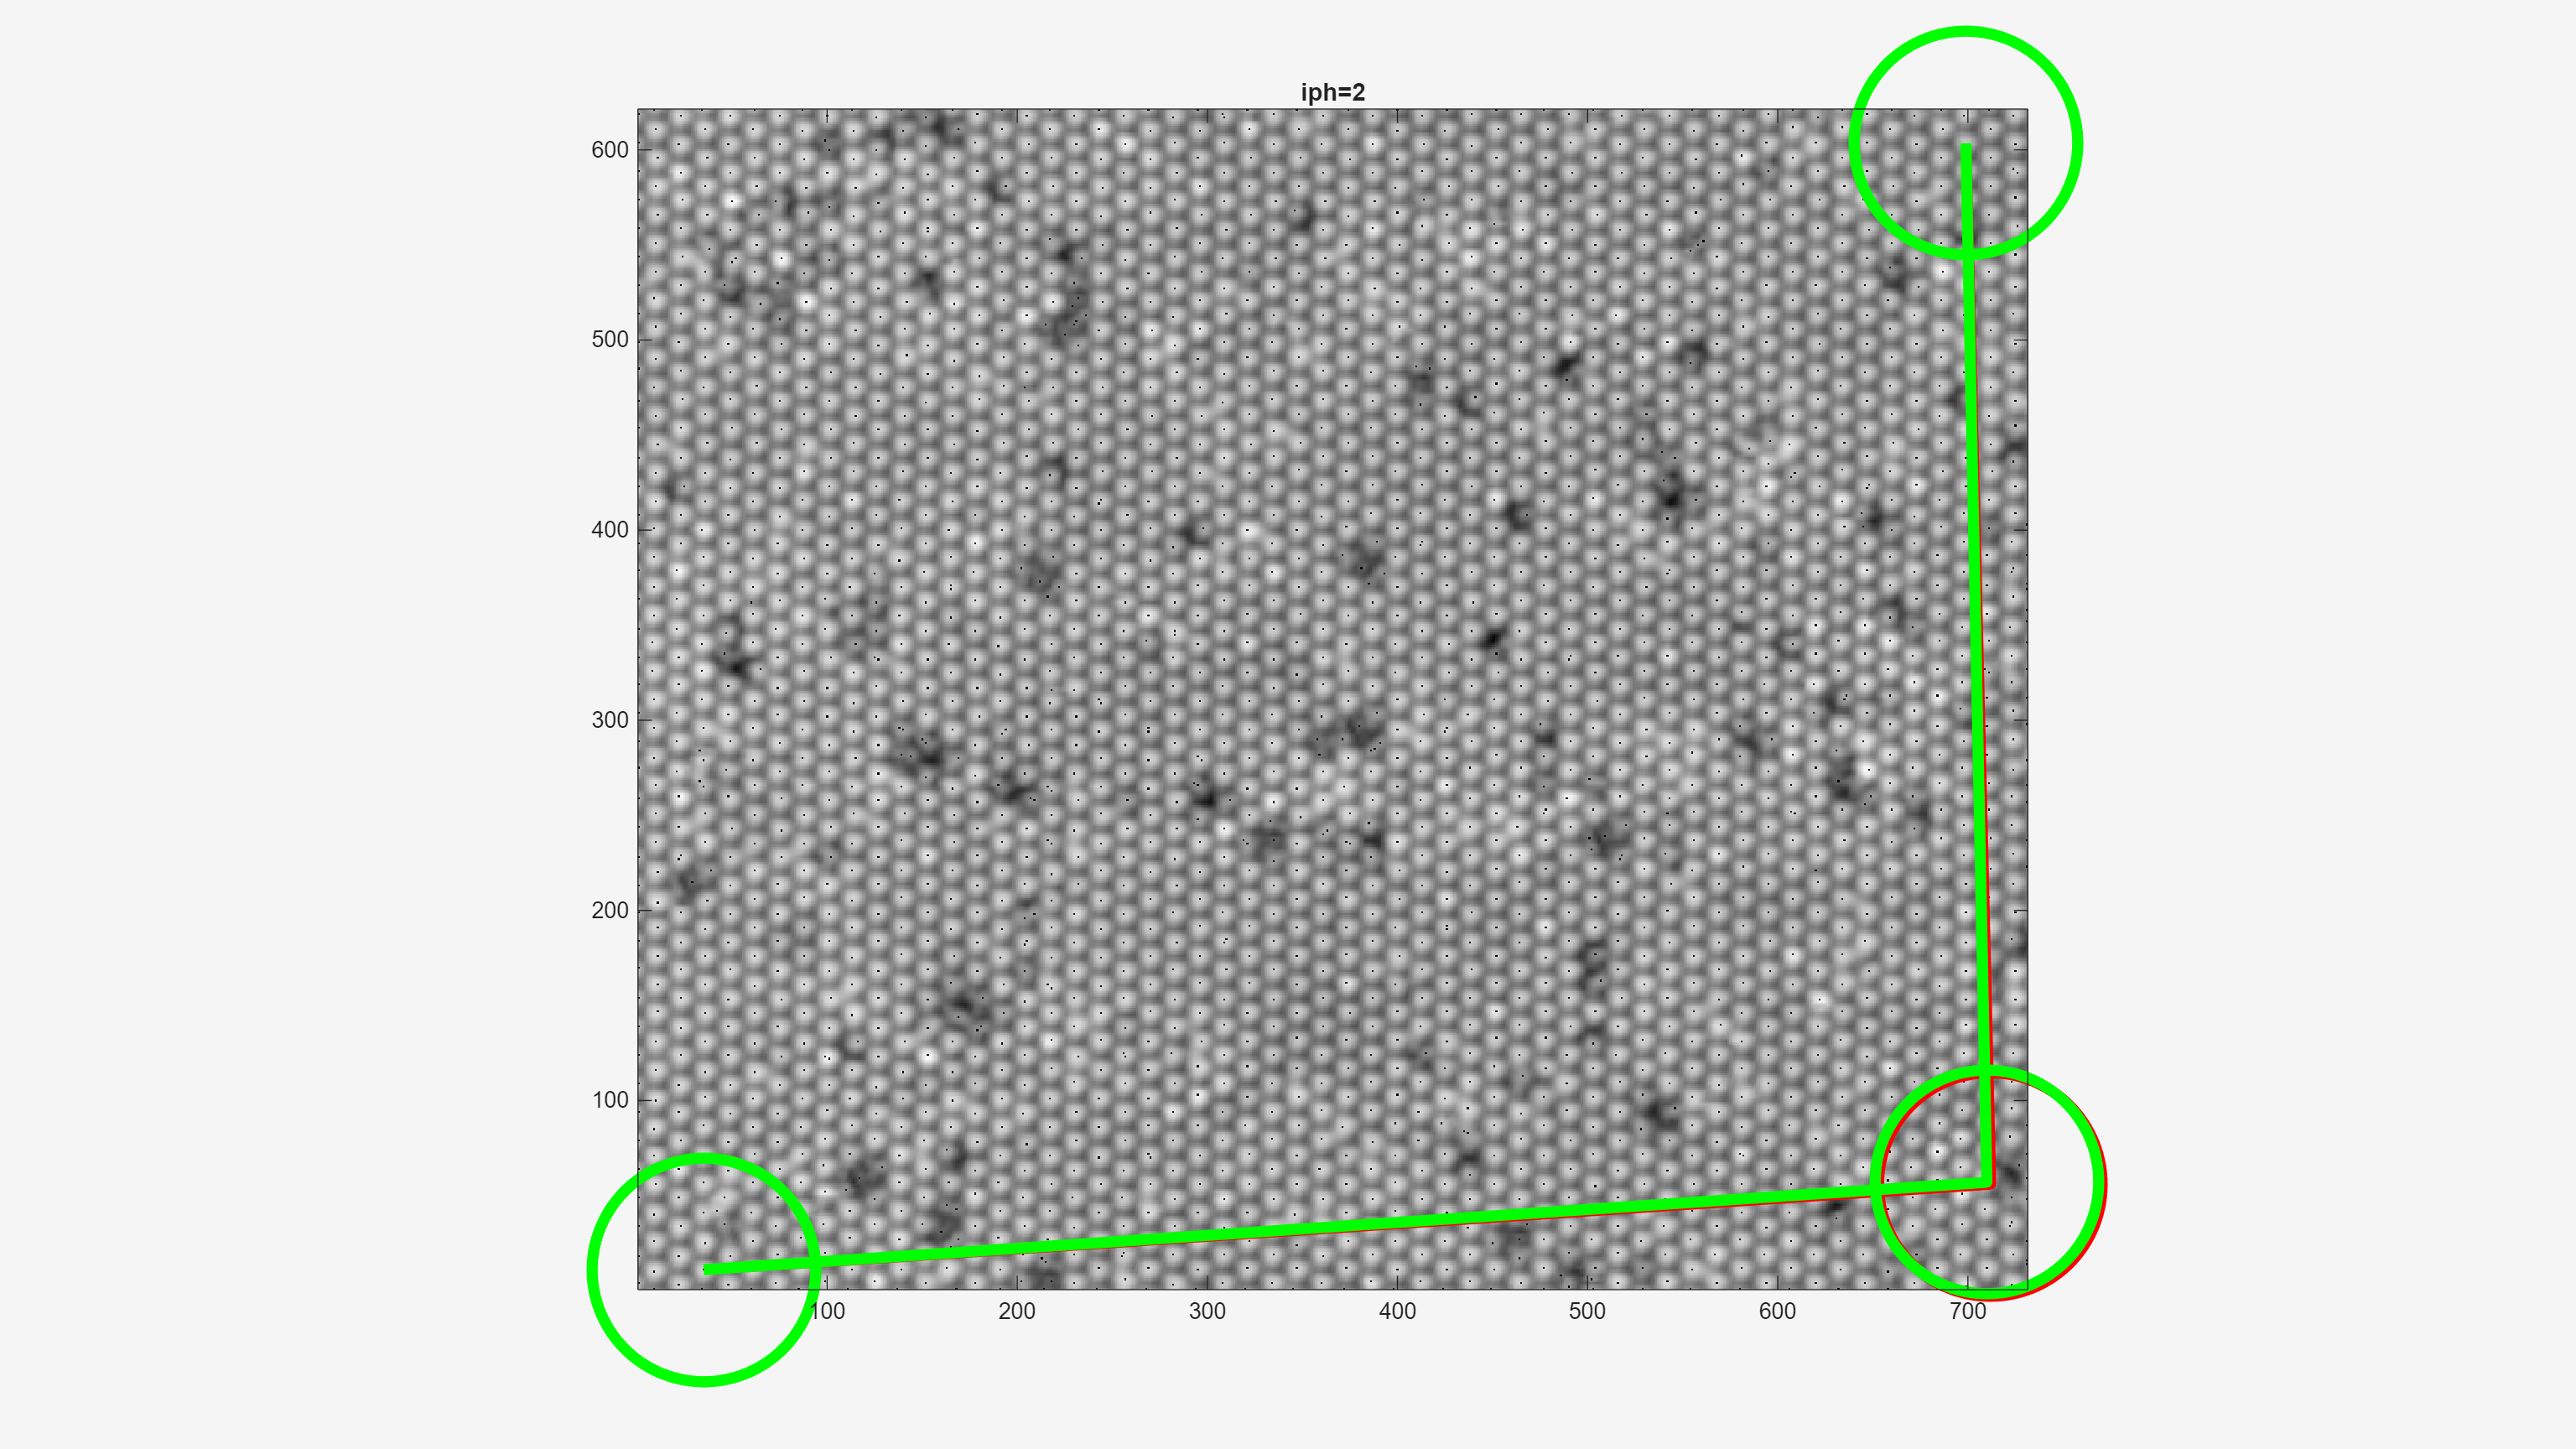

pp3s =   1×2 Line array:

    Line    Line


pp3s(2).LineWidth = 5

## Export final Coordinate

hd.from = currentScript;
hd.at = datetime;
dt(1) = bs(1);
dt(2) = bs(2);

lattCoord.hd = hd

lattCoord = struct with fields:
    hd: [1×1 struct]


lattCoord.dt = dt

lattCoord = struct with fields:
    hd: [1×1 struct]
    dt: [1×2 grid2d]


save ..\od\OneDrive\matlab\RawData\'1T-TaS2(point defect)'\lattCoord.mat lattCoord

function visualize(Z,a)
gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0 1 1]);
f1.Visible = "on";


hold on
a.pBases
hold off
hold on
p = a.pLatticeWin
p.Color = [1 0 0];
p.Marker ="o"
hold off
% hold on
% a.pGridlineWin
% hold off
f = gcf()
go = findobj(f,'type','image')
go.HitTest = 'off'
end

function a = consturctGrid(I_P__C,line_info,szZ)
a = grid2d();
a.a1_stdpts = I_P__C(:,1);
a.a2_stdpts = I_P__C(:,2);
a.offset_stdpts = line_info(:,1,:);
a.sz_stdpts = szZ;
end

function I_P__C = constructBases(line_info)
%P: pixel Coord
%B: line profile Coord
%C: lattice Coord
%Target: I_P__C
b1_x = (line_info(:,2,1) - line_info(:,1,1)) / (line_info(:,3,1)-1);
b2_y = (line_info(:,2,2) - line_info(:,1,2)) / (line_info(:,3,2)-1);
I_P__B = [b1_x 0;0 b2_y];
I_B__C = [1 0;-1/2 1];
I_P__C = I_P__B*I_B__C;
end